# 通信原理实验6

姓名：朱天昊

学号：18308267

邮箱：1312622783@qq.com

## 实验目标

`数字带通传输。`

## 实验条件

MATLAB 2016 and above, Simulink, and Communications System Toolbox .

## Prelab

## Problem 1  仿真对比4ASK信号、8PSK信号、4FSK信号在AWGN信道下的传输性能

假设符号周期为1s，载波频率为10Hz，每个符号周期内采样100个点，仿真4ASK信号、8PSK信号、4FSK信号在AWGN信道下的误码率和误比特率性能，并与理论值进行比较。

**Answer:**

% insert your code here
clc; close all; clear all;
Tb = 1;         %符号周期
fc = 10;        %载波频率
Ns = 100;       % 每个符号采样100个点
ts = 1/Ns;
t = 0:ts:Tb; % 时间向量

c = sqrt(2/Tb)*exp(j*2*pi*fc*t);  % 载波信号
c1 = sqrt(2/Tb)*cos(2*pi*fc*t);   % 同相载波
c2 = -sqrt(2/Tb)*sin(2*pi*fc*t);  % 正交载波

nsym = 10000;   % 总共发送10000个码元
EsN0 = 0:15;    % 符号信噪比取值范围

% 一、4ASK信号
A = [0, 1, 3, 2];       % 本次程序统一使用格雷编码

M = length(A);

snr1 = 10.^(EsN0/10);    % 信噪比转化为线性值

msg = randi([0,3], 1, nsym);   % 生成10000个随机码元，每个码元有四种可能的取值
msg1 = A(msg+1);               % 对码元格雷编码
msgmod = pammod(msg1, M).';   
% pammod将msg1的二进制表示序列中每两位变成一个复信号，如：a+jb (a通过I路，b通过Q路）,但由于这里是幅度调制，所以虚数部分为零
tx = real(msgmod*c)   % 开始载波调制： tx = a*cosw0t-b*sinw0t

tx =    -4.2426   -3.4324   -1.3110    1.3110    3.4324    4.2426    3.4324    1.3110   -1.3110   -3.4324   -4.2426   -3.4324   -1.3110    1.3110    3.4324    4.2426    3.4324    1.3110   -1.3110   -3.4324   -4.2426   -3.4324   -1.3110    1.3110    3.4324    4.2426    3.4324    1.3110   -1.3110   -3.4324   -4.2426   -3.4324   -1.3110    1.3110    3.4324    4.2426    3.4324    1.3110   -1.3110   -3.4324   -4.2426   -3.4324   -1.3110    1.3110    3.4324    4.2426    3.4324    1.3110   -1.3110   -3.4324
   -1.4142   -1.1441   -0.4370    0.4370    1.1441    1.4142    1.1441    0.4370   -0.4370   -1.1441   -1.4142   -1.1441   -0.4370    0.4370    1.1441    1.4142    1.1441    0.4370   -0.4370   -1.1441   -1.4142   -1.1441   -0.4370    0.4370    1.1441    1.4142    1.1441    0.4370   -0.4370   -1.1441   -1.4142   -1.1441   -0.4370    0.4370    1.1441    1.4142    1.1441    0.4370   -0.4370   -1.1441   -1.4142   -1.1441   -0.4370    0.4370    1.1441    1.4142    1.1441    0.4370   -0.4370   -

tx1 = reshape(tx.', 1, length(msgmod)*length(c))   % 调整矩阵行数列数

tx1 =    -4.2426   -3.4324   -1.3110    1.3110    3.4324    4.2426    3.4324    1.3110   -1.3110   -3.4324   -4.2426   -3.4324   -1.3110    1.3110    3.4324    4.2426    3.4324    1.3110   -1.3110   -3.4324   -4.2426   -3.4324   -1.3110    1.3110    3.4324    4.2426    3.4324    1.3110   -1.3110   -3.4324   -4.2426   -3.4324   -1.3110    1.3110    3.4324    4.2426    3.4324    1.3110   -1.3110   -3.4324   -4.2426   -3.4324   -1.3110    1.3110    3.4324    4.2426    3.4324    1.3110   -1.3110   -3.4324


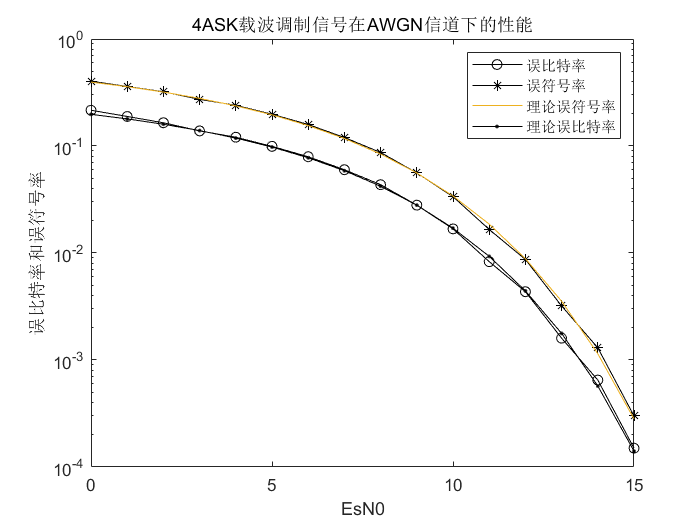

spow = norm(tx1).^2/nsym;    % 求单个码元的平均功率

for i = 1:length(EsN0)
    sigma = sqrt(spow/(2*snr1(i)));   % 根据码元功率求出噪声功率
    rx = tx1 + sigma*randn(1, length(tx1));  %加入高斯白噪声
    rx1 = reshape(rx, length(c), length(msgmod));
    r1 = (c1*rx1)/length(c1);
    r2 = (c2*rx1)/length(c2);
    r = r1 + j*r2;
    y = pamdemod(r, M);
    decmsg = A(y+1);
    
    [err, ber(i)] = biterr(msg, decmsg, log2(M)); % 误码率、误比特率的仿真结果
    [err, ser(i)] = symerr(msg, decmsg);
end

ser1 = 2*(M-1)*qfunc(sqrt(6*snr1/(M^2-1)))/M;     % 误码率、误比特率理论值计算
ber1 = 1/log2(M) * ser1;
semilogy(EsN0, ber, '-ko', EsN0, ser, '-k*', EsN0, ser1, EsN0, ber1, '-k.');
title('4ASK载波调制信号在AWGN信道下的性能');
xlabel('EsN0'); ylabel('误比特率和误符号率');
legend('误比特率', '误符号率', '理论误符号率', '理论误比特率');

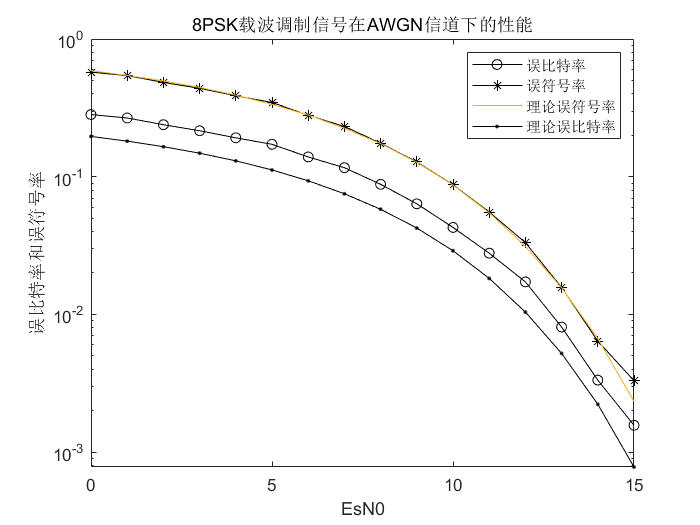


% 二、8PSK信号
P = [0, 1, 2, 3, 6, 7, 4, 5];
M = length(P);
snr1 = 10.^(EsN0/10);    % 信噪比转化为线性值
msg = randi([0,7], 1, nsym);
msg1 = P(msg+1);
msgmod = pskmod(msg1, M).';   % pskmod将msg1中每两位变成一个复信号，如：a+jb (a通过I路，b通过Q路）

tx = real(msgmod*c);    % 开始载波调制
tx1 = reshape(tx.', 1, length(msgmod)*length(c));   % 调整矩阵行数列数
spow = norm(tx1).^2/nsym;     % 求单个码元的平均功率

for i = 1:length(EsN0)
    sigma = sqrt(spow/(2*snr1(i)));    % 根据码元功率求出噪声平均功率
    rx = tx1 + sigma*randn(1, length(tx1));  % 加入高斯白噪声
    rx1 = reshape(rx, length(c), length(msgmod));
    r1 = (c1*rx1)/length(c1);
    r2 = (c2*rx1)/length(c2);
    r = r1 + 1j*r2;
    y = pskdemod(r, M);               
    decmsg = P(y+1);
    [err, ber(i)] = biterr(msg, decmsg, log2(M));  % 误码率、误比特率的仿真结果
    [err, ser(i)] = symerr(msg, decmsg);
end
ser1 = 2*qfunc(sqrt(2*snr1)*sin(pi/M));     % 误码率、误比特率理论值的计算
ber1 = 1/log2(M) * ser1;
semilogy(EsN0, ber, '-ko', EsN0, ser, '-k*', EsN0, ser1, EsN0, ber1, '-k.');
title('8PSK载波调制信号在AWGN信道下的性能');
xlabel('EsN0'); ylabel('误比特率和误符号率');
legend('误比特率', '误符号率', '理论误符号率', '理论误比特率');


% 三、4FSK信号
F = [0, 1, 3, 2];       % 本次程序统一使用格雷编码

M = length(F);

snr1 = 10.^(EsN0/10);    % 信噪比转化为线性值

msg = randi([0,3], 1, nsym);
msg1 = F(msg+1);
msgmod = fskmod(msg1, M, 0.25, 100).';
tx = real(msgmod*c);    % 开始载波调制
tx1 = reshape(tx.', 1, length(msgmod)*length(c));   % 调整矩阵行数列数
spow = norm(tx1).^2/nsym;

for i = 1:length(EsN0)
    sigma = sqrt(spow/(2*snr1(i)));
    rx = tx1 + sigma*randn(1, length(tx1));  %加入高斯白噪声
    rx1 = reshape(rx, length(c), length(msgmod));
    r1 = (c1*rx1)/length(c1);
    r2 = (c2*rx1)/length(c2);
    r = r1 + j*r2;
    y = fskdemod(r, M, 0.25, 100);
    decmsg = F(y+1);
    
    [err, ber(i)] = biterr(msg, decmsg, log2(M));
    [err, ser(i)] = symerr(msg, decmsg);
end

ser1 = (M-1)*qfunc(sqrt(snr1));
ber1 = 1/log2(M) * ser1;
semilogy(EsN0, ber, '-ko', EsN0, ser, '-k*', EsN0, ser1, EsN0, ber1, '-k.');
title('4FSK载波调制信号在AWGN信道下的性能');
xlabel('EsN0'); ylabel('误比特率和误符号率');
legend('误比特率', '误符号率', '理论误符号率', '理论误比特率');


**仿真结果分析：**

1）本次实验的三种调制方式都用到了IQ调制。将码元的a、b信息写成复数形式，再与载波的复数形式e^(jwct)相乘取实部，便可得到a、b通过I路和Q路调制后的信号：a*cos(wct) - b*sin(wct).

2）4ASK采用4个不同的幅度分别表示四进制码元，每个码元含有2bit信息。4ASK单位频带的信息传输速率比2ASK高，但抗噪声性能比2ASK稍差。当已调信号通过AWGN信道时，信号波形受到的扰动较大，误码率也随之增大。

3）8PSK信号的载波有八种相位，每个码元有3bit信息。当码元信号通过IQ调制时，各个信号会均匀的分布在星座图上的单位圆上。同时，由于实验采用格雷码编码，所以星座图上相邻相位所代表的三个比特只有一位不同。由于相位误差造成错判至相邻相位上的概率最大，这样编码可使总的误比特率降到最低。

4）4FSK采用4个不同的频率分别表示四进制的码元，每个码元含有2bit信息。由于使用了IQ调制，不同频率的码元互相正交。4FSK的码元采用4个不同的频率载波，所以它占用较宽的频带。解调时，使用带通滤波器将各个频率区分，并设置好判决门限，便可完成基带信号的调制、解调。

## Lab

## Problem 1  差分PSK

1）假设消息数据序列经过Gray编码后分别是[1 2 3 0 3 2 1 1]，分别画出它们的4PSK和4DPSK调制信号波形。假设载波频率为1Hz。

2）用基带等效的方式仿真8-DPSK载波调制信号在AWGN信道下的误码率和误比特率，并与理论值相比较。

**Answer:**

% insert your code here
clc; close all; clear all;
M = 4;
msg = [1, 2, 3, 0, 3, 2, 1, 1];  % 格雷编码后的消息序列
Tb = 1;         %符号周期
fc = 1;        %载波频率
Ns = 100;       % 每个符号采样100个点
ts = 1/Ns;
t = 0:ts:Tb; % 单个符号的时间向量
x = 0:ts:length(msg)*Tb;

c = sqrt(2/Tb)*exp(j*2*pi*fc*t);  % 载波信号

msg_psk = pskmod(msg, M).';
msg_dpsk = dpskmod(msg, M).';
tx_psk = real(msg_psk*c);
tx_psk = reshape(tx_psk.', 1, length(msg)*length(t));
tx_dpsk = real(msg_dpsk*c);
tx_dpsk = reshape(tx_dpsk.', 1, length(msg)*length(t));

% (1) 画出4PSK和4DPSK的波形
subplot(2,1,1);
plot(x, tx_psk(1:length(x)));
title('4PSK信号波形');
xlabel('时间t'); ylabel('已调信号幅度');
subplot(2,1,2);
plot(x, tx_dpsk(1:length(x)));
title('4DPSK信号波形');
xlabel('时间t'); ylabel('已调信号幅度');
figure;

% (2) 8-DPSK的误码率和误比特率
Tb = 1;         %符号周期
fc = 10;        %载波频率
Ns = 100;       % 每个符号采样100个点
ts = 1/Ns;
t = 0:ts:Tb; % 时间向量

c = sqrt(2/Tb)*exp(j*2*pi*fc*t);  % 载波信号
c1 = sqrt(2/Tb)*cos(2*pi*fc*t);   % 同相载波
c2 = -sqrt(2/Tb)*sin(2*pi*fc*t);  % 正交载波

nsym = 10000;   % 总共发送10000个码元
EsN0 = 0:15;    % 符号信噪比取值范围
P = [0, 1, 2, 3, 6, 7, 4, 5];
M = length(P);
snr1 = 10.^(EsN0/10);    % 信噪比转化为线性值
msg = randi([0,7], 1, nsym);
msg1 = P(msg+1);
msgmod = dpskmod(msg1, M).';   
tx = real(msgmod*c);    % 开始载波调制
tx1 = reshape(tx.', 1, length(msgmod)*length(c));   % 调整矩阵行数列数

spow = norm(tx1).^2/nsym;

for i = 1:length(EsN0)
    sigma = sqrt(spow/(2*snr1(i)));
    rx = tx1 + sigma*randn(1, length(tx1));  %加入高斯白噪声
    rx1 = reshape(rx, length(c), length(msgmod));
    r1 = (c1*rx1)/length(c1);
    r2 = (c2*rx1)/length(c2);
    r = r1 + j*r2;
    y = dpskdemod(r, M);               
    decmsg = P(y+1);
    [err, ber(i)] = biterr(msg, decmsg, log2(M));
    [err, ser(i)] = symerr(msg, decmsg);
end
ser1 = 2*qfunc(2*sqrt(snr1)*sin(pi/2/M));     % 理论值的计算
ber1 = 1/log2(M) * ser1;
semilogy(EsN0, ber, '-ko', EsN0, ser, '-k*', EsN0, ser1, EsN0, ber1, '-k.');
title('8DPSK载波调制信号在AWGN信道下的性能');
xlabel('EsN0'); ylabel('误比特率和误符号率');
legend('误比特率', '误符号率', '理论误符号率', '理论误比特率')

**仿真结果分析：**

1）DPSK把前一码元的相位当作参考相位，把相移phik当作是相对于前一码元相位的相移。如此一来，DPSK在解调时可以预防PSK中出现的倒pi现象。DPSK首先把要传输的码元序列转换为相对

码，再使用PSK的方法对相对码进行调制、解调，最后在判决输出端对码元序列进行相对码解码，便可完成一次完整的DPSK调制。

2）MPSK和MDPSK的抗噪声能力比MASK和MFSK要强，即使在高斯白噪声信道中传输它所受的影响也不算大。它的解调方式和MPSK类似，有极性比较法和相位比较法。

## 实验总结

通过这次实验，掌握了数字带通传输原理，回答了关于……的问题……。

## 答：通过这次实验，我掌握了ASK、FSK、PSK的调制解调原理以及它们的抗噪声性能。本次实验全部使用了多进制数字调制，每个码元可以传输多个bit信息，这样提高了频带利用率，增强了通信系统的有效性。但多进制调制一定程度上增加了判决的难度，使得抗噪声性能下降。对于ASK，其优点是设备简单，频带利用率较高，缺点是抗噪声性能差，对信道特性变化敏感。FSK则抗干扰能力强，但占用频带宽，频带利用率低。PSK的抗噪声能力最强，并且传输效率也高，因此应用更加广泛